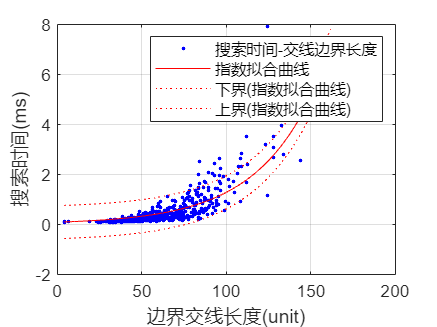

fitresult =      常规模型 Exp1:
     fitresult(x) = a*exp(b*x)
     系数(置信边界为 95%):
       a =     0.07947  (0.06816, 0.09078)
       b =     0.02772  (0.02646, 0.02899)

gof = 包含以下字段的 struct :
           sse: 96.7404
       rsquare: 0.6521
           dfe: 601
    adjrsquare: 0.6515
          rmse: 0.4012


file = "data\perf_gcs_rand_corridor.csv";
data = importdata(file, ',', 1);
tottime = data.data(:, 4);
bordersize = data.data(:, 5);

% fig = figure();
% scatter(bordersize, tottime, "black",".");
% axis([0,160,0,4]);
% grid on;
% xticks(0:20:160);
% yticks(0:0.5:4);

[fitresult, gof] = fit_bordersize_searchtime2(bordersize, tottime)